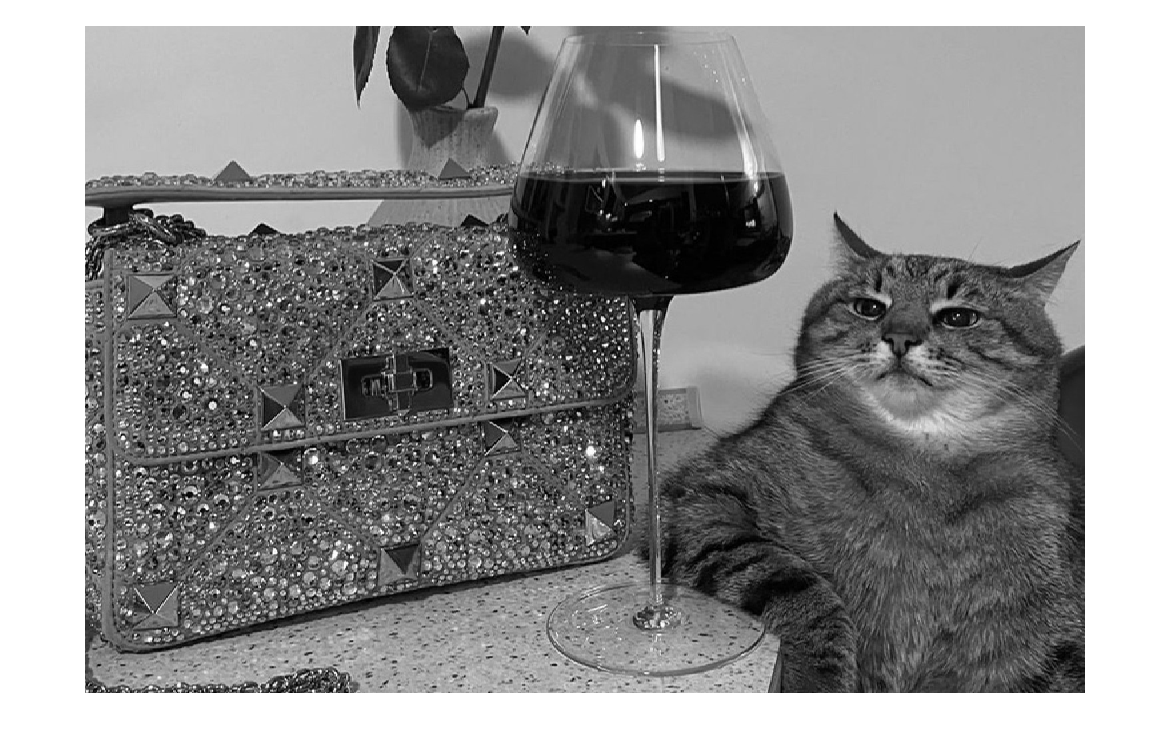

image = imread('task_2.jpg');
image = double(im2gray(image)) / 255;

imshow(image);

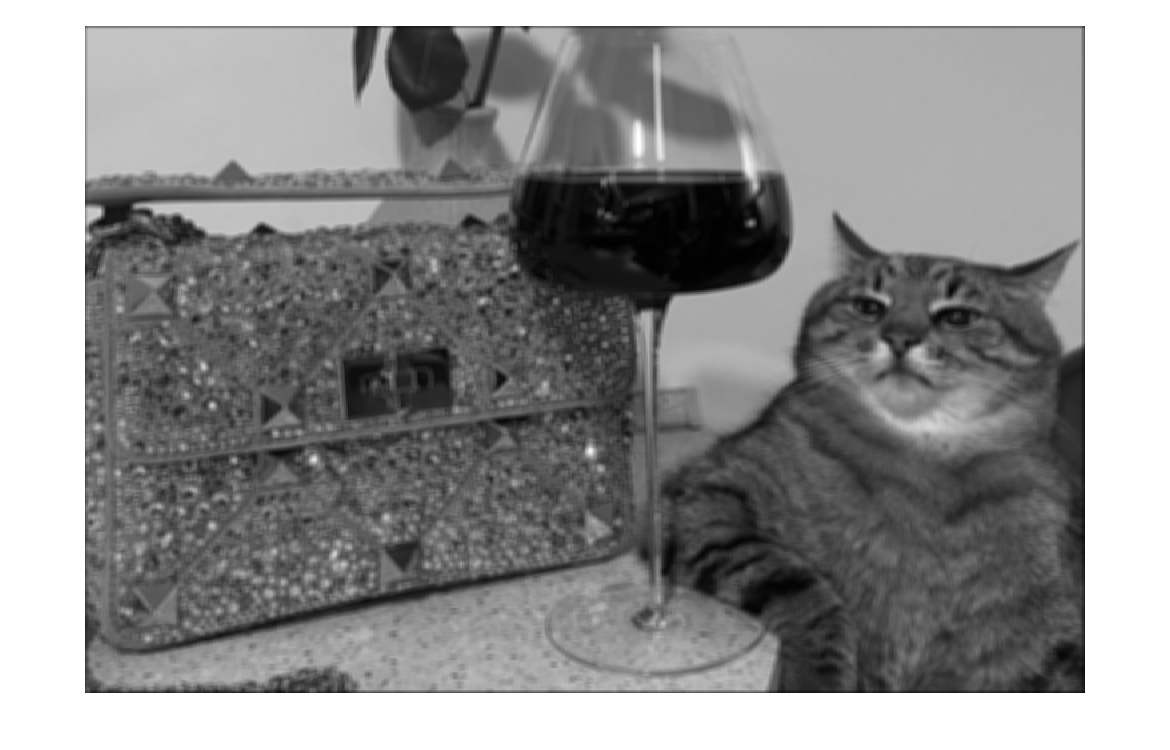

n = 10;

block_kernel = ones(n) / n^2;
image_block_blur = blur(image, block_kernel);

imshow(image_block_blur);

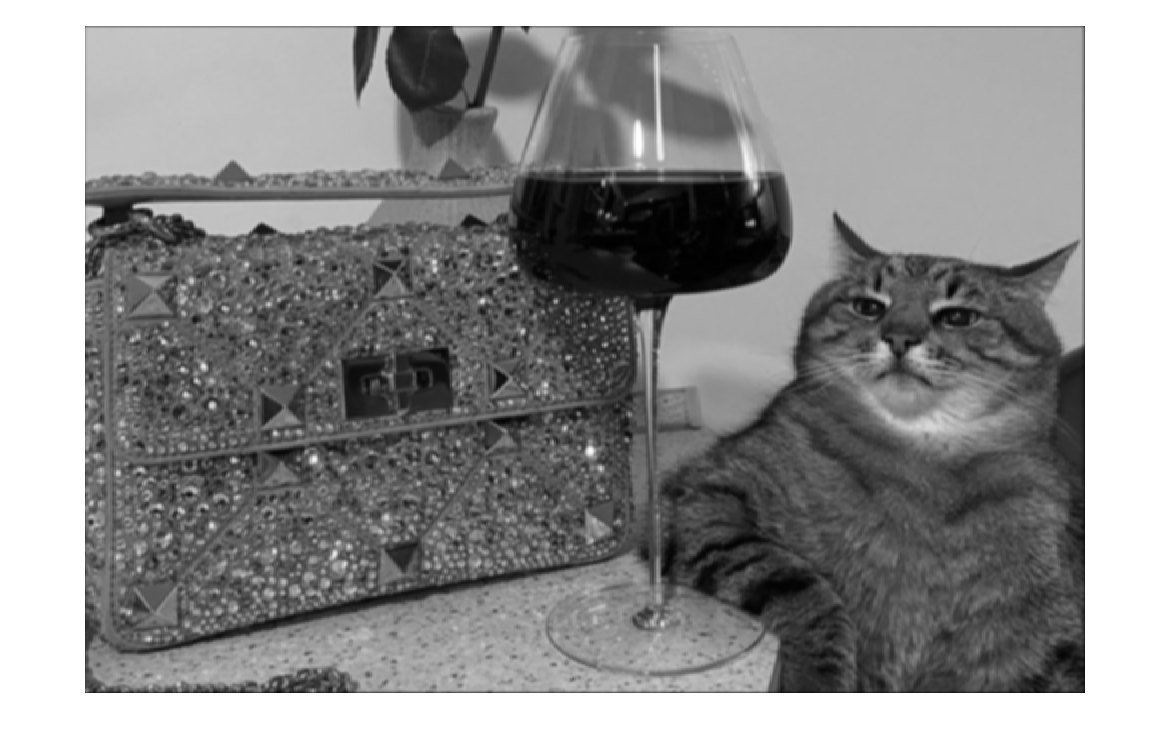

gaussian_kernel = gaussianKernel(n);
image_gaussian_blur = blur(image, gaussian_kernel);

imshow(image_gaussian_blur);

[image_height, image_width] = size(image);
[kernel_height, kernel_width] = size(block_kernel);

image_fourier = fftshift(fft2( ...
    image, ...
    image_height + kernel_height - 1, image_width + kernel_width - 1));

block_kernel_fourier = fftshift(fft2( ...
    block_kernel, ...
    image_height + kernel_height - 1, image_width + kernel_width - 1));

gaussian_kernel_fourier = fftshift(fft2( ...
    gaussian_kernel, ...
    image_height + kernel_height - 1, image_width + kernel_width - 1));

image_block_fourier = image_fourier .* block_kernel_fourier;
image_gaussian_fourier = image_fourier .* gaussian_kernel_fourier;

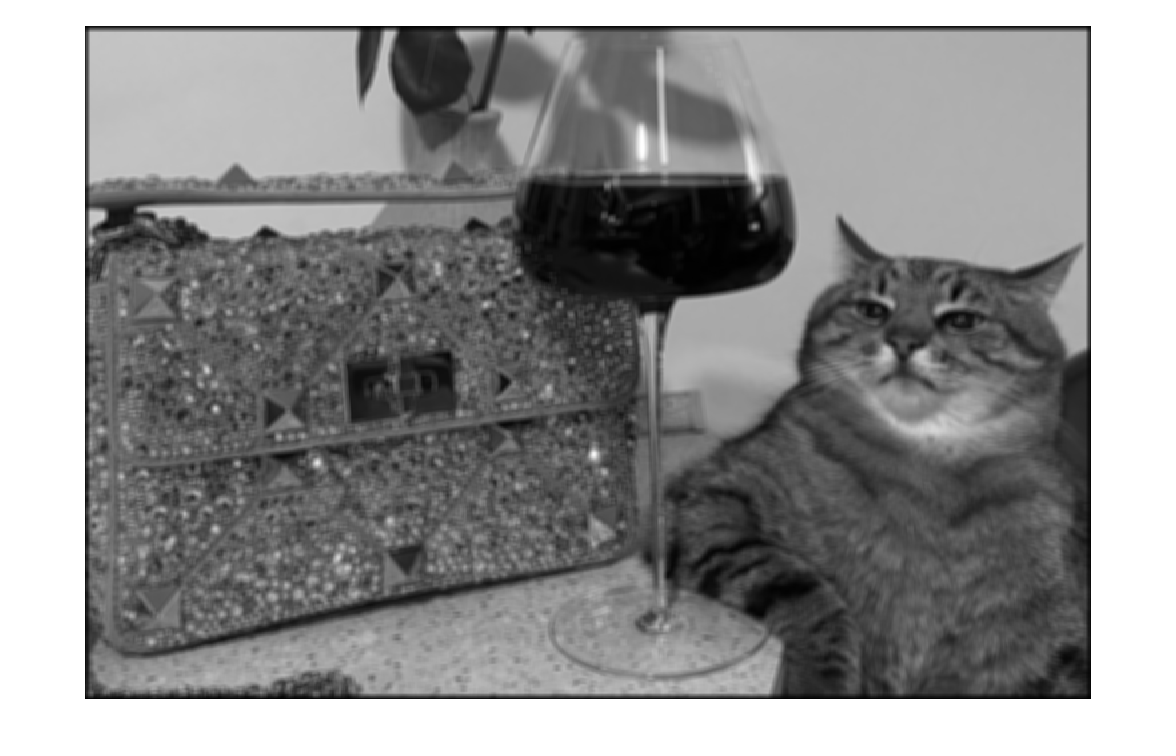

image_block = ifft2(fftshift(image_block_fourier));
image_block = abs(image_block);

image_gaussian = ifft2(fftshift(image_gaussian_fourier));
image_gaussian = abs(image_gaussian);

imshow(image_block);

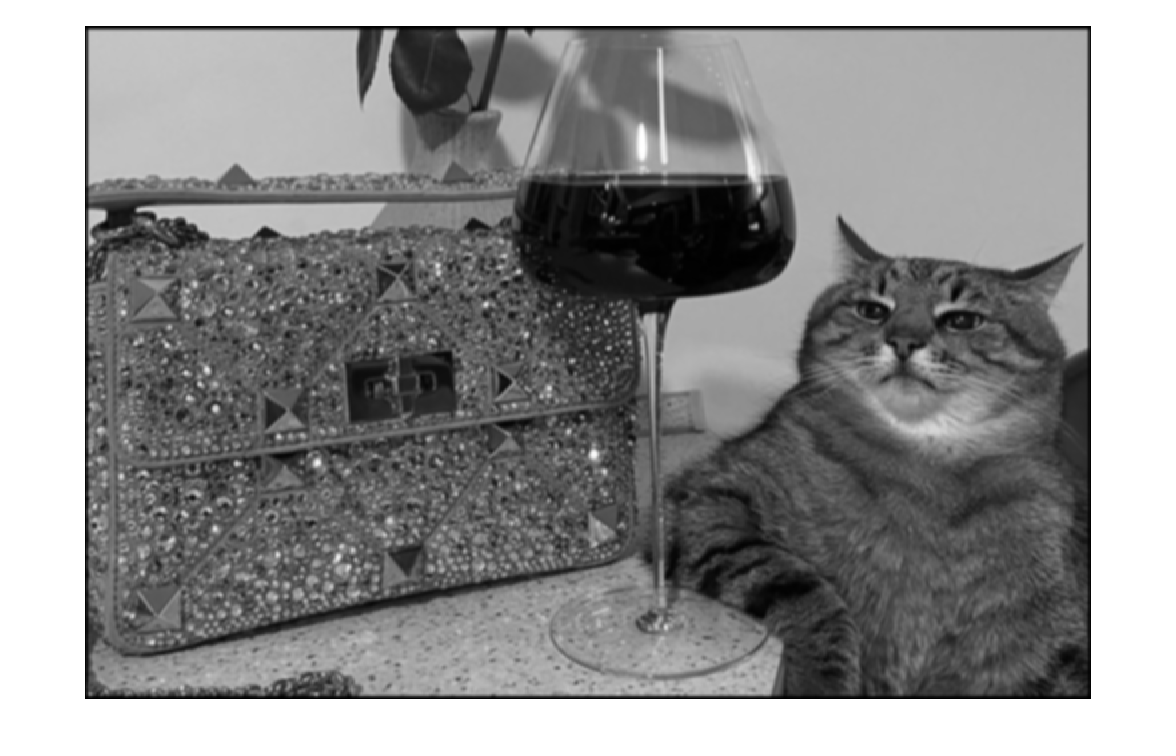

imshow(image_gaussian);

function kernel = gaussianKernel(n)
    kernel = zeros(n, n);
    for x = 1:n
        for y = 1:n
            power = (x - (n + 1) / 2)^2;
            power = power + (y - (n + 1) / 2)^2;
            power = power * ((-9) / (n^2));

            kernel(x, y) = exp(power);
        end
    end

    kernel = kernel / sum(kernel(:));
end

function image = blur(image, kernel)
    image = conv2(image, kernel, 'same');
end